## Q2)

## i.

sampling_frequency_div2 = 2000;
amplitude_m = [1 1];
phase_m = [0 0];
total_duration = 150*10^(-3)

total_duration = 0.1500

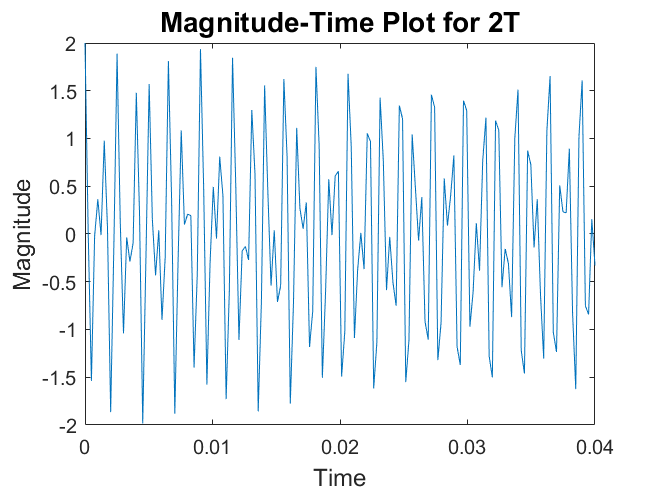


% First we generate function handles of summed sinusoidals using generator_summed_sinusoids

% Function handle 1: 770 Hz & 1209 Hz, 40ms;
frequency_m_1 = [770 1209];
handle_1 = generate_summed_sinusoidals(2,amplitude_m,frequency_m_1,phase_m);
duration_1 = 40*10^(-3);

t = linspace(0,duration_1,2*sampling_frequency_div2*duration_1); 

sampled_1 = handle_1(t);

figure
plot(t,sampled_1);
xlabel('Time','Fontsize',12);
ylabel('Magnitude','Fontsize',12);
title('Magnitude-Time Plot for 2T','Fontsize',14);
xlim([0 duration_1]);

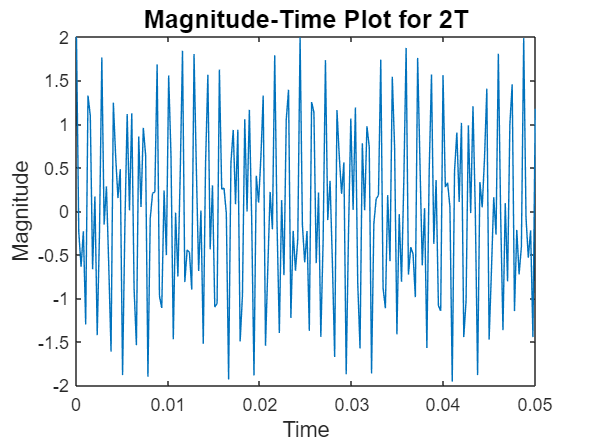




% Function handle 2: 697 Hz & 1477 Hz, 50ms;
frequency_m_2 = [697 1477];
handle_2 = generate_summed_sinusoidals(2,amplitude_m,frequency_m_2,phase_m);
duration_2 = 50*10^(-3);

t = linspace(0,duration_2,2*sampling_frequency_div2*duration_2); 

sampled_2 = handle_2(t);

figure
plot(t,sampled_2);
xlabel('Time','Fontsize',12);
ylabel('Magnitude','Fontsize',12);
title('Magnitude-Time Plot for 2T','Fontsize',14);
xlim([0 duration_2]);

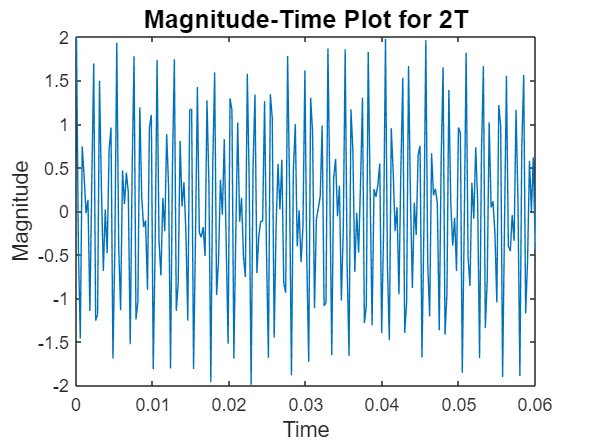


% Function handle 3: 941 Hz & 1336 Hz, 60ms;

frequency_m_3 = [941 1336];
handle_3 = generate_summed_sinusoidals(2,amplitude_m,frequency_m_3,phase_m);
duration_3 = 60*10^(-3);

t = linspace(0,duration_3,2*sampling_frequency_div2*duration_3); 

sampled_3 = handle_3(t);

figure
plot(t,sampled_3);
xlabel('Time','Fontsize',12);
ylabel('Magnitude','Fontsize',12);
title('Magnitude-Time Plot for 2T','Fontsize',14);
xlim([0 duration_3]);

% Then we sum these handles according to their corresponding intervals

t = linspace(0,total_duration,2*sampling_frequency_div2*total_duration)

t =          0    0.0003    0.0005    0.0008    0.0010    0.0013    0.0015    0.0018    0.0020    0.0023    0.0025    0.0028    0.0030    0.0033    0.0035    0.0038    0.0040    0.0043    0.0045    0.0048    0.0050    0.0053    0.0055    0.0058    0.0060    0.0063    0.0065    0.0068    0.0070    0.0073    0.0075    0.0078    0.0080    0.0083    0.0085    0.0088    0.0090    0.0093    0.0095    0.0098    0.0100    0.0103    0.0105    0.0108    0.0110    0.0113    0.0115    0.0118    0.0120    0.0123



length(t)

ans = 600

summed_signal = zeros(1,length(t));
size_of_signal = length(t);

end_of_signal_1 = size_of_signal*duration_1/total_duration

end_of_signal_1 = 160

end_of_signal_2 = size_of_signal*duration_2/total_duration + end_of_signal_1

end_of_signal_2 = 360


summed_signal(1:end_of_signal_1)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sampled_1

sampled_1 =     2.0000    0.0126   -1.5374   -0.0204    0.3638   -0.0110    0.9772    0.0711   -1.8649   -0.1208    1.8891    0.1153   -1.0401   -0.0350   -0.2878   -0.0950    1.4793    0.2112   -1.9840   -0.2425    1.5706    0.1512   -0.4334    0.0387   -0.8993   -0.2444    1.8111    0.3602   -1.8827   -0.3112    1.0850    0.0982    0.2089    0.1929   -1.3988   -0.4249    1.9362    0.4741   -1.5772   -0.2950    0.4935   -0.0479    0.8096    0.4015   -1.7296   -0.5928    1.8450    0.5129   -1.1095   -0.1773


summed_signal(1:end_of_signal_1) = sampled_1;
summed_signal(end_of_signal_1+1: end_of_signal_2) = sampled_2;
summed_signal(end_of_signal_2 +1:size_of_signal) = sampled_3;

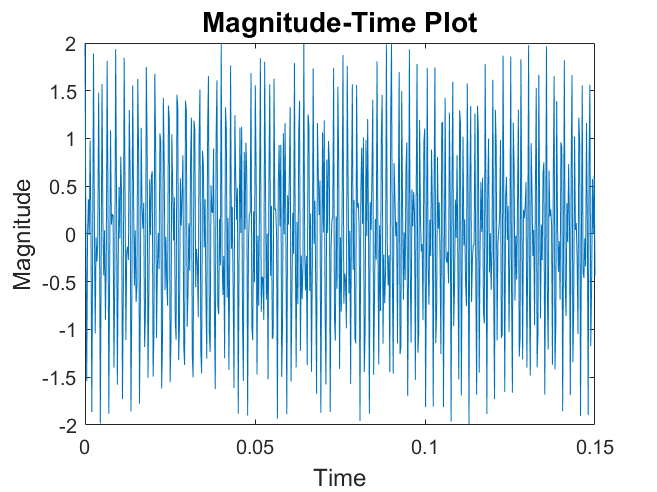

figure
plot(t,summed_signal);
xlabel('Time','Fontsize',12);
ylabel('Magnitude','Fontsize',12);
title('Magnitude-Time Plot','Fontsize',14);

% xlim([0.035 0.055]);


#### Wİndow Type Comparison:

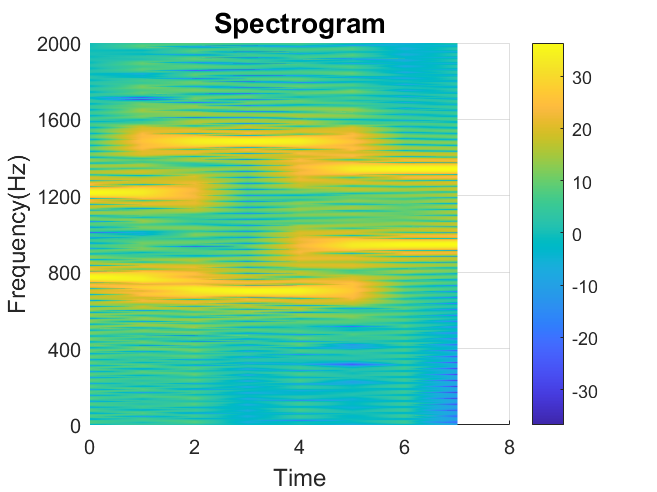

window_length = 128;
window_shift = 64;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'rectwin',sampling_frequency_div2)

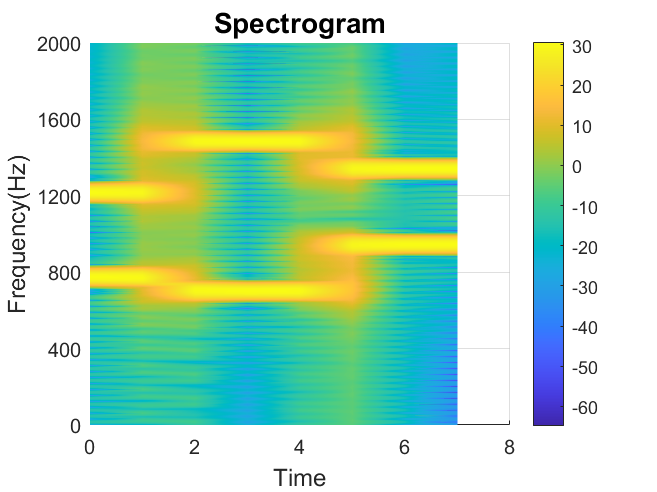


figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'hamming',sampling_frequency_div2)

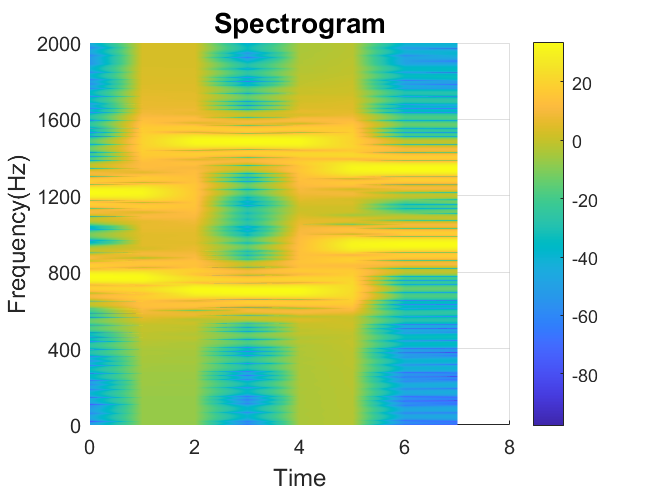


figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'tukeywin',sampling_frequency_div2)

Comments: The main lobe becomes of the window in Hamming is wider compared to the Rectangular window, which leads to a decrease in time resolution. However since the side lobes become smaller as we go to the edges, which increases the frequency resolution. This is also the case in Tukey window where the side lobes get smaller. However, this improvement in frequency resolutioncauses a wider main lobe in the time domain, which can reduce time resolution as can bee seen in the image. The highest frequency resolution is observed for Hamming window whereas the highest time resolution is observed for Rectangular.

Window shift constant, window length changes:

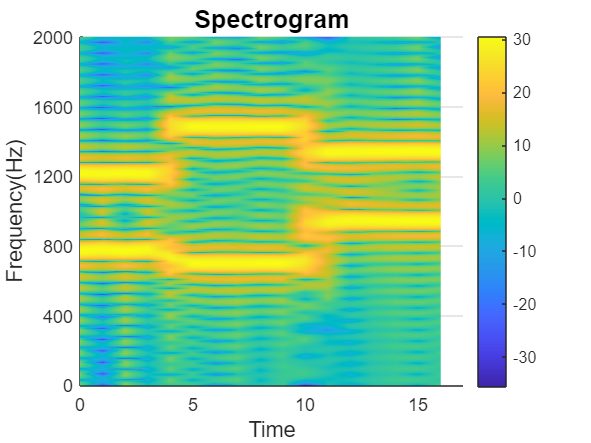

window_length = 64;
window_shift = 32;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'rectwin',sampling_frequency_div2)

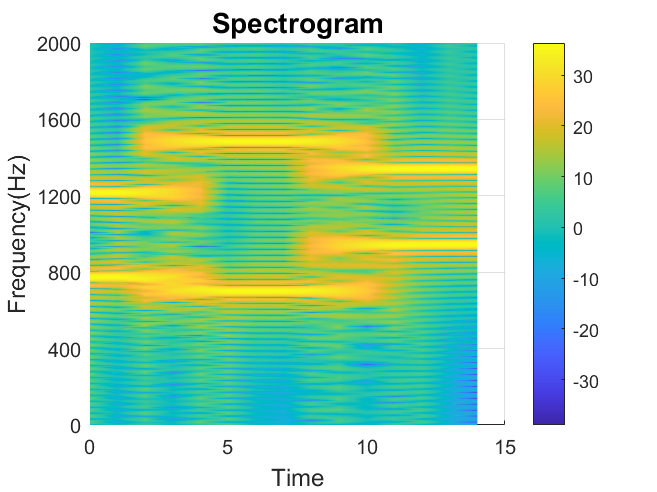


window_length = 128;
window_shift = 32;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'rectwin',sampling_frequency_div2)

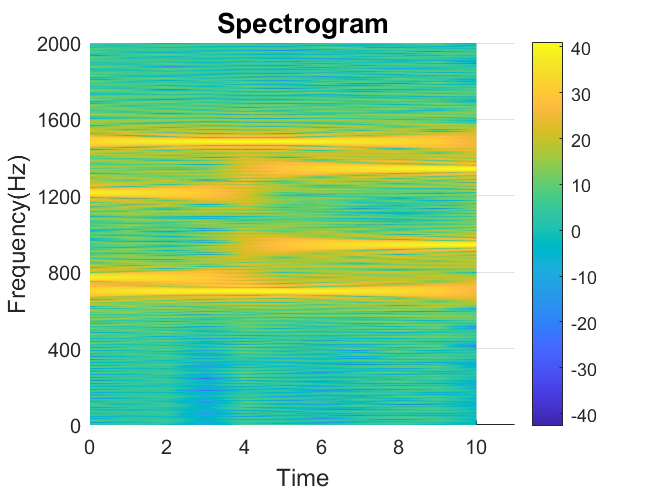


window_length = 256;
window_shift = 32;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'rectwin',sampling_frequency_div2)

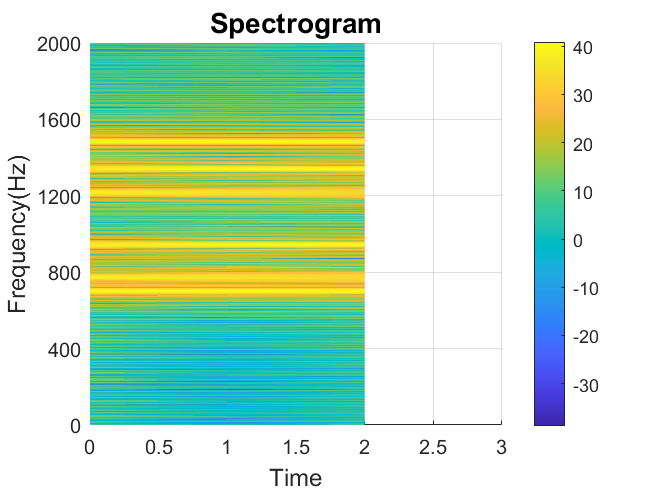


window_length = 512;
window_shift = 32;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'rectwin',sampling_frequency_div2)

**Comments:** As window length increases while window shift is sonstant, we observe that the frequency resolution increases while the time resolution decreases. For the last case where window length is 1048, the frequency changing time points are not visible at all. A shorter window will capture a smaller segment of the signal, which results in a better time localization of the frequency content.

#### Window length constant, window shift changes:

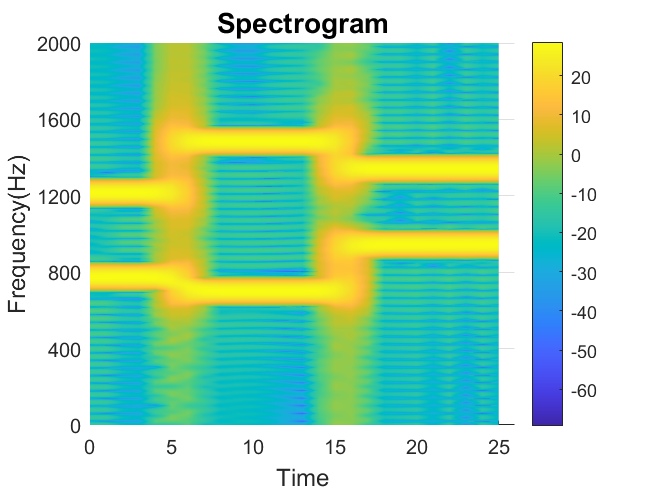

window_length = 100;
window_shift = 20;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'hamming',sampling_frequency_div2)

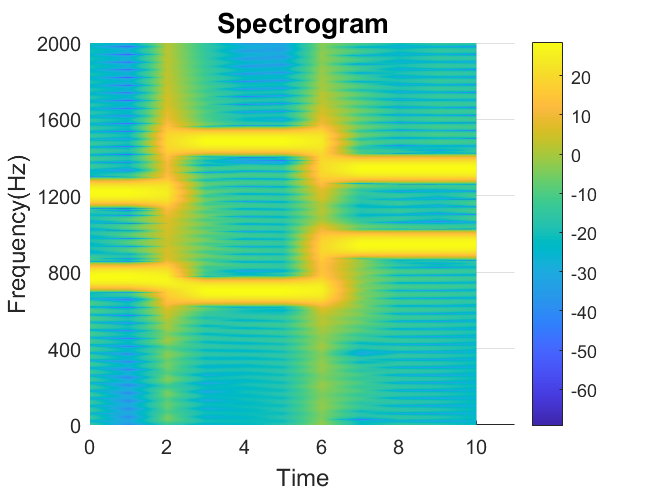


window_length = 100;
window_shift = 50;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'hamming',sampling_frequency_div2)

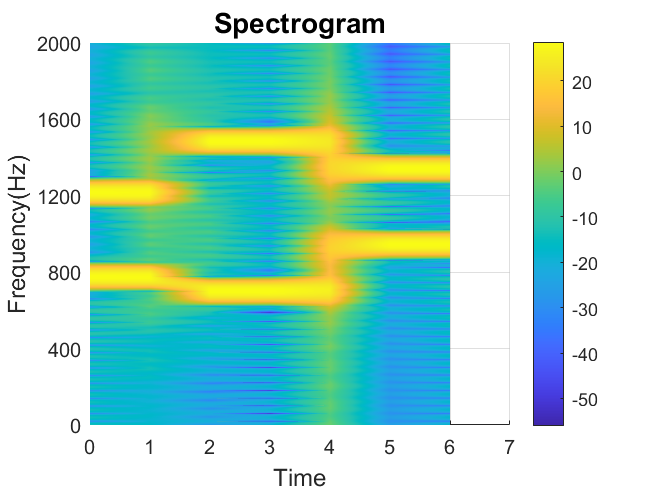


window_length = 100;
window_shift = 75;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'hamming',sampling_frequency_div2)

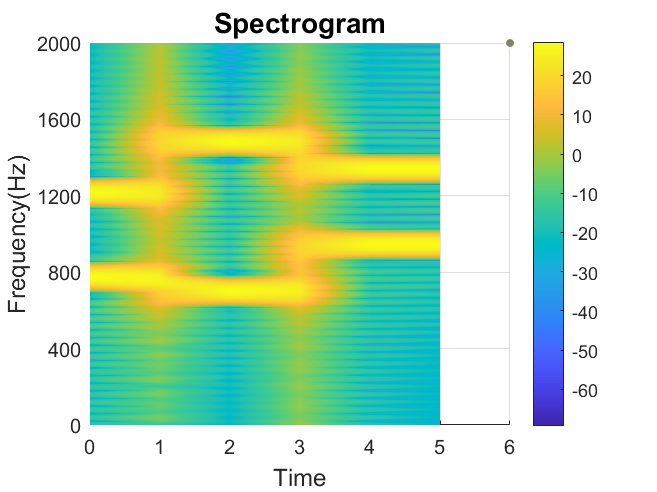


window_length = 100;
window_shift = 100;

figure
spectogram_plotter_generated_signals_vol2(summed_signal,window_length,window_shift,'hamming',sampling_frequency_div2)

**Comments:** Opposite to the previous case, as we increase window shift while keeping the window length constant, we observe that the time resolution increases but the frequency resolution decreases. This is due to the fact that as the larger windows overlap more and thus the frequency content is lost more.